# AccelerationInFreeFall

*D. Carlsmith*

Template analysis of data for acceleration in free fall experiment. 

## Introduction

A line-frequency-triggered spark generator can be used in a free fall experiment in which a falling mass drags a paper-tape through the periodic spark, leaving visible marks in the tape at regular time intervals. If the generator is triggered on peaks in the sinusoidal (AC) power, the interval is of (1/60) s in the US and (1/50) s elsewhere. The displacement of the mass over time is deduced from measurements of the locations of the marks in the tape.

This Live Script simulates the experiment and data analysis.

## Generate some fake data and plot it

h= 2; % drop height in m
g= 9.803636; % acceleration of gravity in Chamberlin Hall

Get total drop time assuming the mass is dropped from rest and uniformly accelerated downwards by gravity and subject to no air drag or tape friction, and that the tape is massless. The displacement  is$x(t)=(1/2)gt^2$ so the time to to travel a distance h is $\sqrt{2h/g}$.

tmax = sqrt(2*h/g); % maximum time (s)
f = 60 ;        % spark generator frequency (Hz)
dt=1/f;         % time interval between sparks (s)

Create a vector of measurement times corresponding to sparks. Note the [start:increment:stop] sequence construction used produces a row vector so we transpose that to get a column vector. 

(Feel free to remove the semicolon at the end of the line and re-run the section to see the result of the command, or copy the command into the command window and play with it, then re-run the script in case you overwrote some variable.)

t=[0:1/f:tmax]';% spark times ('=> column vector)

Compute the predicted corresponding displacements. 

x=g*t.^2/2;% displacements 
% (.^ applies ^ element by element)

`t` is a vector so we used `.^2` rather than `^2` to tell MATLAB to square each element in `t`, returning a vector `t.^2`. A scalar like g times a vector is natively understood to mean multiply each element of the vector by the scalar. So `g*t.^2/2` is a vector and MATLAB creates a vector x with elements assigned the values we want. All we did was add a period (.) to an expression for scalars. Powerful stuff, this notation.

N = length(t);   % number of points/dots
xError = 0.0001; % magnitude of position error

We use `ones` to autogenerate a column of 1's in the next statement and multiply by a scalar to get a vector all the elements of which are identical.

xErr = xError*ones(N,1); % estimated position error vector

Add normally distributed noise with zero mean and a common position measurement error for all points. The function  [normrnd](https://www.mathworks.com/help/stats/normrnd.html)`,` as called, provides a vector of numbers normally distributed about 0 with standard deviation (std) equal to xError. Each number gets added to a displacement entry to make emulate real data in which uncorrelated effects contaminate each measurement:

x1=x+normrnd(0,xError,[N,1]);

Generate an independent sample of measurements each with same error distribution parameters assuming again random deviations unrelated to previous ones. `Normrand` starts with a seed (that we can reset) and spews out uncorrelated (mostly) numbers thereafter. This new sample emulates a repeating of the entire experiment with all sources of noise, not just that associated with measuring the locations of dots on the tape, but also noise in the generation of those dots.

x2=x+normrnd(0,xError,[N,1]);

Plot the 1st fake data sample with error bars using [errorbar](https://www.mathworks.com/help/matlab/ref/errorbar.html). The error bars are hard to see but essential. The '.' tells errorbar to use a point to represent the value, not say an asterix.

errorbar(t,x1,xErr,'.'); xlabel (' time (s)');ylabel('x (m)')
title(' Displacement versus time in free fall')

Put a `hold on` the figure so calls to `plot` will not make a new figure and plot but instead overlay subsequent plots until a `hold off `command is issued or a new `figure` command is issued.

hold on

Overlay the 2nd fake data sample on the same plot, with an offset for visibility.

offset = 0.2;
errorbar(t,x2+offset,xErr,'.');
legend;

Fit the first data sample to a polynomial using a least squares method [`polyfit`](https://www.mathworks.com/help/matlab/ref/polyfit.html) which returns a vector P (values of coefficients) and a structure S with other error related information,  and use polyval to evaluate the fitted polynomial at all the times, then superpose the fit on the same plot.

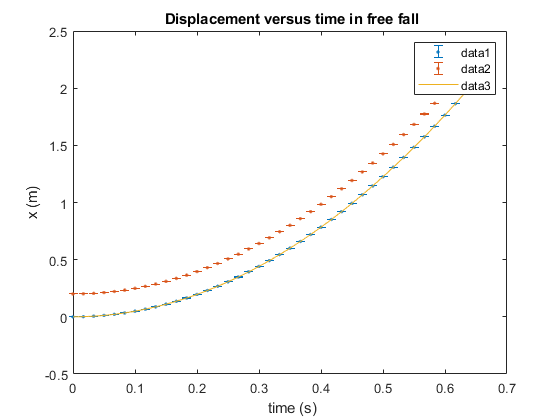

degree=2; % the degree of the polynomial
[P,S] = polyfit(t,x1,degree); %fit for polynominal 
Y = polyval(P,t);% compute poloynomial at times
plot(t,Y)% superpose on plot of original points

We can open the figure in a new window (try it!) and zoom in and see that the fit passes through most of the data points within error. There should be a few points outside the curve within error. More incisive is to make a residuals plot and look there for any trends suggesting the data points are correlated.

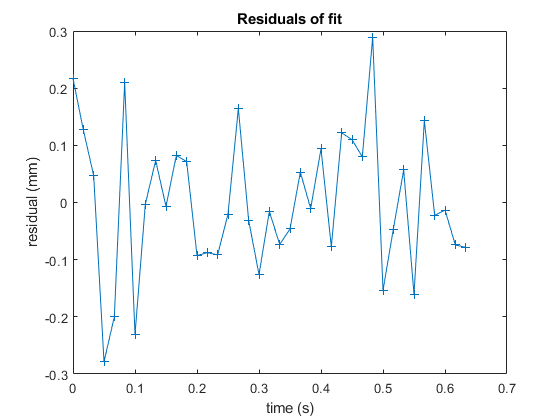

residuals=Y-x1; % differences between fit and data
figure % we want a new figure for this; different scale
plot(t,residuals*1000,'+-'); title('Residuals of fit');
xlabel('time (s)');ylabel('residual (mm)')% note scale change

There are no trends. A histogram of the residuals should look like a normal distribution. Otherwise it was a poor fit.

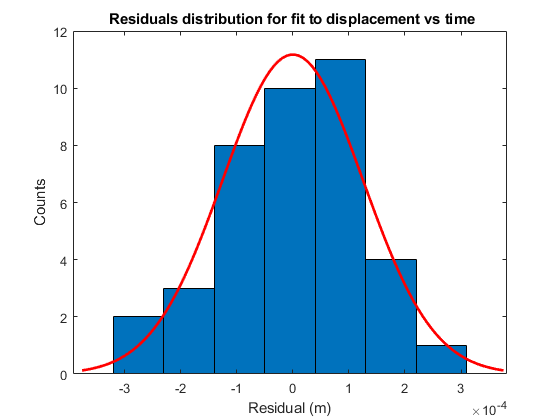

histfit(residuals)
title(' Residuals distribution for fit to displacement vs time')
xlabel('Residual (m)');ylabel('Counts')

Is this a normal distribution? A statistical test of that hypothesis is possible. It would entail looking at the $\chi^2$ of the residuals of the fit to the residuals where the standard errors in each bin would be estimated as the square root of the count. In our case, those errors are of order 2-3 counts and the histfit curve is withinthe std  error in all but maybe the lowest bin. Let's just say it looks reasonable. But take note that this is not an incisive test. Systematic trends in the residuals of the fit to the actual data can be hidden when projected into a histogram. that the distribution of residuals to a fit are consistent with normal is a necessary but insufficient condition for declaring a fit good in the sense of putting a bound on the possiblity of contributions outside the model of uniform acceleration, e.g. effects of air drag.

Print the fit coefficients (x= P(1)t^2+P(2)t+P(3) for degree =2). The first is seen to be large, the other two negligible.

P

P =     4.9017   -0.0001    0.0001


To extract the errors of the parameters with this fitting function, per the MATLAB documentation for `polyfit`, we must extract, from the returned data structure S, the matrix R, the number of degrees of freedom df, and the norm of the residuals (of the deviations between fit and data)

R=S.R; df=S.df;normr=S.normr;

We then compute the inverse Rinv of the matrix R to estimate the covariance matrix Cov thusly:

Rinv=inv(R); Cov = (Rinv*Rinv')*normr^2/df

Cov = 	1.0e+-6 *

    0.4298   -0.2722    0.0280
   -0.2722    0.1845   -0.0215
    0.0280   -0.0215    0.0035


The diagonal elements of Cov are the estimates of the standard variances (std^2 ) of the parameters and the standard deviations (std's) are the square roots of these so we use `diag` to get the diagonal elements of Cov and take the square root of all of them using .^ as follows:

stdHistFit=(diag(Cov)).^(1/2)

stdHistFit = 	1.0e+-3 *

    0.6556
    0.4295
    0.0588


The quadratic term in our fit is evidently (given the fit values) the only significant term and the corresponding parameter value P(1) is about g/2 as expected. That the values of the other two parameters are of order their errors is an indication these parameters are not needed. If we dropped them and fit to a quadratic term alone, we would pick up two lost degrees of freedom applicable to the fit for coefficient of the quadratic alone, improving the estimated error on that sole parameter a bit (2 out of N) subject to the caveat that our hypothesis is there is ONLY that term. The change in the error estimate for g hardly matters if N is large compared to 2.

We compute our best estimate of g and the standard error (given the hypothesis that the data is described by our 3-term polynomial) to be

g_estimate = 2*P(1)

g_estimate = 9.8033

g_estimate_std = 2*stdHistFit(1)

g_estimate_std = 0.0013

We would report this as 9.8035+-0.0011 or 9.8035(11) where the error is statistical in nature - we would expect it to improve with more data points. 

## **Systematic errors**

The statistical error just derived assumes the model is correct and that the measurements were unbiased. Additional uncertainty may be associated with possible biases. For example, we assumed the mean spark frequency was 60 Hz but without a measurement have no basis other than maybe someone's word that that is true and no idea how far off from that value the spark frequency might have been in our measurements. We should either measure it somehow or study the operation of the spark generator and literature on the stability and value of the 60 cycle alternating current power that triggers the spark generator to estimate a possible bias. If the result of that investigation was an estimated standard uncertainty of say 0.6 Hz or 1%, and since our estimate of g derives from the quadratic term, there is an additional uncertainty in g of about 2% from the time scale. The standard uncertainties of other imaginable systematic effects should similarly be measured or estimated and all of these combined "in quadrature" ( $\sigma_{sys}^{tot}=\sqrt{ \sum_i\sigma_i^2}$ ) and this error quoted separately. 

Mock up what this experiment looks like on the paper tape.

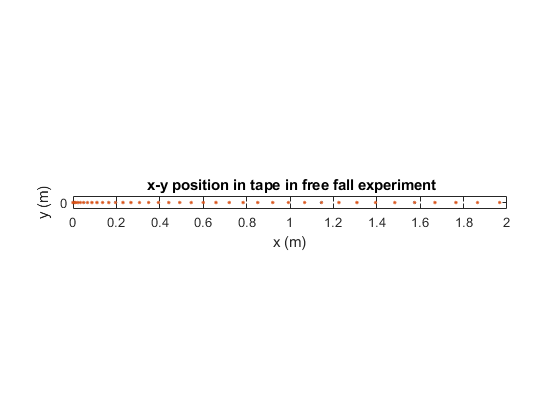

figure
y1=zeros(length(t),1); y2 = y1;
plot(x1,y1,'.'); xlabel ('x (m)');ylabel('y (m)')
tapewidth = 0.0254;% tape if probably 1 inch wide
pbaspect([1 tapewidth 1])% set plot aspect ratio [x y z]
title(' x-y position in tape in free fall experiment')
hold on; plot(x2,y2,'.');

## Export and import data

You may have entered vector values by hand in your code. Here is how to save vectors to a csv file to share with others.

m=[x1 x2 t];% three column matrix
filename = 'csvlist.dat';
csvwrite(filename,m); % write matrix to file (no column labels!)
type csvlist.dat; % type the file to check

-0.00013077,-8.6488e-05,0
0.0013183,0.0013586,0.016667
0.0054807,0.00543,0.033333
0.012612,0.012317,0.05
0.022063,0.021895,0.066667
0.033905,0.034151,0.083333
0.049322,0.048932,0.1
0.066792,0.066727,0.11667
0.087137,0.087022,0.13333
0.11036,0.11018,0.15
0.13614,0.13616,0.16667
0.16474,0.16491,0.18333
0.19622,0.196,0.2
0.23025,0.23015,0.21667
0.26702,0.26685,0.23333
0.30643,0.30648,0.25
0.34845,0.34846,0.26667
0.39358,0.39351,0.28333
0.44133,0.44122,0.3
0.49159,0.49165,0.31667
0.54475,0.5448,0.33333
0.60055,0.60048,0.35
0.65899,0.65887,0.36667
0.72032,0.72022,0.38333
0.78421,0.78418,0.4
0.8511,0.85125,0.41667
0.92034,0.92039,0.43333
0.99251,0.99269,0.45
1.0674,1.0675,0.46667
1.1448,1.1452,0.48333
1.2256,1.2254,0.5
1.3085,1.3084,0.51667
1.3942,1.3942,0.53333
1.4829,1.4828,0.55
1.5739,1.574,0.56667
1.668,1.668,0.58333
1.7646,1.7648,0.6
1.8641,1.8641,0.61667
1.9662,1.9662,0.63333


Here is how to read in a csv file (that has no column labels) that someone shared with you. (You can also double click the file within MATLAB to bring up an import app.)

m = csvread(filename)

m =    -0.0001   -0.0001         0
    0.0013    0.0014    0.0167
    0.0055    0.0054    0.0333
    0.0126    0.0123    0.0500
    0.0221    0.0219    0.0667
    0.0339    0.0342    0.0833
    0.0493    0.0489    0.1000
    0.0668    0.0667    0.1167
    0.0871    0.0870    0.1333
    0.1104    0.1102    0.1500


Make column vectors from a csv-file-import matrix

x1=m(:,1), x2=m(:,2);, t=m(:,3); % 

x1 =    -0.0001
    0.0013
    0.0055
    0.0126
    0.0221
    0.0339
    0.0493
    0.0668
    0.0871
    0.1104


## Histogram differences between independent measurements, fit to a normal distribution, and superpose fit on the histogram.

 Take the difference between successive displacement points and convert to mm (the appropriate scale)

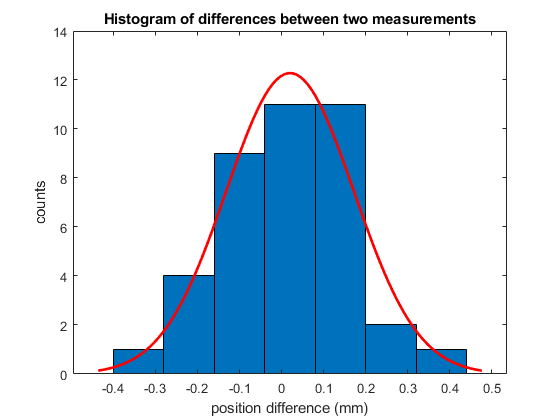

diffx_mm=(x1-x2)*1000;
figure % start a new figure or histfit will overwrite the last one
histfit(diffx_mm)% fit and plot in one go
xlabel('position difference (mm)'); ylabel('counts')
title(['Histogram of differences between two measurements'])

`Histfit` uses `fitdist `and we have to rerun `fitdist` to get the parameters of the fit. If you don't want the plot, just call `fitdist`.

Fit for normal distribution and get fit parameters

distname='Normal';% select to fit for normal distribution
pd = fitdist(diffx_mm,distname) ; % catch results in pd

Extract mean and std parameters from structure `pd` returned by fit.

meandiffx = pd.mu

meandiffx = 0.0201

stddiffx = pd.sigma

stddiffx = 0.1520

Notice that the mean is 0 within error, while we expect standard deviation (on a difference of values, each distributed with std $\sigma_x$ of $\sqrt{2}\sigma_x$ = 1.41 mm and find an estimated difference a bit lower. There is an error on the error estimate which is a story unto itself we save for another time. Broad brush, the estimate of the std is sensitive to fluctuations in the data and for small samples has an expected std of order the estimated std itself.

## Plot average velocities at each time interval for first sample

Get differences between displacements, i.e. the displacements in each interval between sparks. 

displacementIncrement = x1(2:N)-x1(1:N-1);
N1=length(displacementIncrement);
aveVelocity=displacementIncrement/dt; % average velocity
aveTime = t(2:N)-dt/2; % set time to middle of interval

Now plot aveVelocity versus aveTime. This approximates the derivative of x(t). The slope could be used to estimate g from the average of the velocity differences between time intervals per time interval, in a high school class, but it is a bad idea.

I recommend always fitting a model to the full data directly, even if such a fit is nonlinear, so as to not introduce hidden correlations.

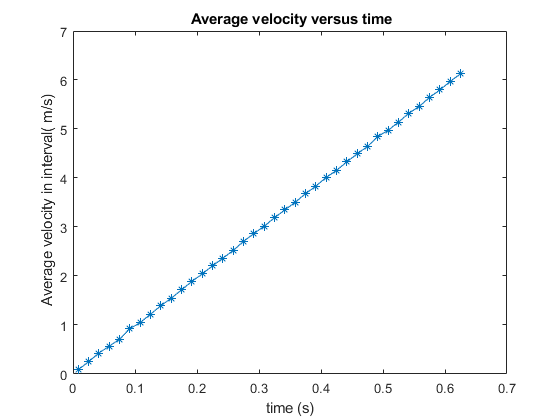

plot(aveTime,aveVelocity,'*-')
xlabel('time (s)');ylabel(' Average velocity in interval( m/s)')
title(' Average velocity versus time')

Each element of aveVelocity is correlated with its neighbor elements. If random error causes x(n+1) to decrease, v(n) decreases while v(n+1) increases. A fitting procedure that neglects these correlations and assumes each aveVelocity element is independent of the rest will give an incorrect estimate of the error on the slope. In fact, the average of the velocities is just the average velocity computed from x(1) and x(N) alone

 
$$\sum v_i /(Ndt)= \sum (x_i-x_{i-1})/Ndt = (x_N-x_1)/Ndt$$
 

so, in effect, averaging the velocites over intervals to estimate acceleration amounts to neglecting the full power of the data. You might as well have not collected the intermediate values.

Let's check this statement, showcasing the function `mean`.

aveacceleration = mean(aveVelocity)/dt

Array indices must be positive integers or logical values.

endsAcceleration = (x(N)-x(1))/(N1*dt^2)

The error on the acceleration found this way would, by propagation of errors, be the relative error on $x_N-x_1$  (or $\sqrt{2}\sigma_x$) divided by $N1 dt^2$.

endsAccelerationError= sqrt(2)*xError/(N1*dt^2)

The ratio of this error to the error we found using all of the data in a quadratic fit is

BadWayOverGoodWay = endsAccelerationError/g_estimate_std

**Warning:**

The polyfit method assumes the errors on each measured point have a similar distribution (common standard deviation), not just that they are uncorrelated. It deduces the mean deviation from the data itself, from the residuals between fit and data. From this it derives the covariance of the fitted parameters. If the data points have different errors or are correlated, the assumptions are invalid. 

You may have been taught to take a logarithm or otherwise manipulate the data before drawing a line through it. Taking a logarithm of the data or in fact any function of the data and fitting THAT to a functional form is a BAD procedure because it neglects the impact on the errors. The error on the log(y(x)) given by propagation of errors,

 $\sigma_{log(y(x))}= {1\over y(x)}\sigma_x$,

depends on the value of x. A fit to log(y(x)) should account for the variation in the errors of the points, i.e. be a weighted fit, not the default in MATLAB and elsewhere, and is more complex to implement. We may have an opportunity to use weighted fits with a different experiment in which the technique is unavoidable.